2. Reprezentati pe acelasi grafic f si polinomul sau de interpolare Hermite.

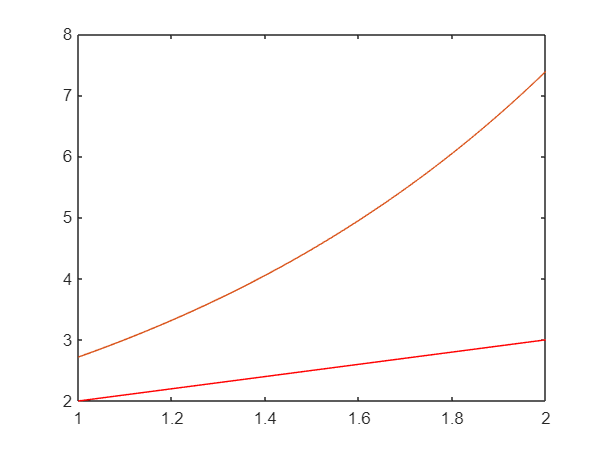

nodes = [0 1 2];
nodevals = exp(nodes);

t = 1 : 0.01 : 2;
res = interpolareHermiteMultiplePoints(nodes, nodevals, nodevals, t);

plot(t, res, 'red');
hold on;
resexp = exp(t);
plot(t, resexp);
hold off;

3. Scrieti o rutina care reprezinta grafic o cubica parametrica Hermite (o curba care trece prin doua puncte date si are în acele puncte tangente date).

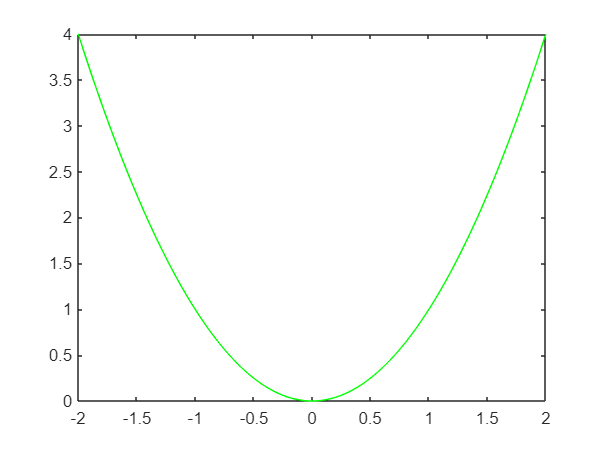

% functia x^2 pe intervalul [-2, 2]
x = [-2 2]; % punctele -2 si 2
f = [4 4]; 
fd = [-4 4];

t = -2 : 0.01 : 2;
res = interpolareHermiteMultiplePoints(x, f, fd, t);

plot(t, res, 'green');

Practic 1

fprintf("Hermite:");

Hermite:

interpolareHermite([0 1 2], [exp(0) exp(1) exp(2)], [exp(0) exp(1) exp(2)], 0.25)

ans =    1.250000000000000



fprintf("Real:");

Real:

exp(0.25)

ans =    1.284025416687741



fprintf("Lagrange:");

Lagrange:

interpolareLagrange([0 1 2], [exp(0) exp(1) exp(2)], 0.25)

ans =    1.152774290676084


2.

format long
x = [0.3, 0.32, 0.35];
y = sin(x);
yy = cos(x);
noduri = [0.34];

d = interpolareHermite(x,y,yy,noduri);
sin(noduri)

ans =    0.333487092140814


d

d =    0.333733666226364


sin(noduri) - d

ans =     -2.465740855494003e-04




x = [0.3, 0.32, 0.33, 0.35];
y = sin(x);
yy = cos(x);
noduri = [0.34];

d = interpolareHermite(x,y,yy,noduri);
sin(noduri)

ans =    0.333487092140814


d

d =    0.333733666226364


sin(noduri) - d

ans =     -2.465740855494003e-04
